
clear

global m process_noise measurement_noise N C_d stepper_pos
m = 1;
N = 5;  %5 dimensions


%init data array
    data.z_true(1) = 0;
    data.v_true(1) = 100;
    data.a_true(1) = -9.8;
   



dt = 0.01;  %seconds
t_range = 0:dt:15; %time



state = [data.z_true(1); data.v_true(1); data.a_true(1); 350; 0.001]; %init the state with a good estimate
state_cov = diag([2 1 0.5 1 0]); %come up with a dummy State Covariance Matrix to initalize the filter
process_noise = diag([0.3 0.3 0.3 0.01 0]);   %this is the uncertainty of the propogation function
measurement_noise = diag([10 0.5]);


%Loop stuff
target_apogee = 300;
Kp = 0.001;

data.stepper_pos(1) = 0;
stepper_pos = data.stepper_pos(1);




% ============Loop==========
for t = 1:length(t_range)-1
% for t = 1:1000

    data.z_kf(t) = state(1);
    data.v_kf(t) = state(2);
    data.a_kf(t) = state(3);
    data.Apogee_kf(t) = state(4);
    data.C_d_kf(t) = state(5);

    data.time(t) = t_range(t);
  
    
    %propogate true state by ODE model
    C_d = data.C_d_kf(t);
    [~, D] = ode45(@rate_func, [t_range(t):dt/2:t_range(t+1)], [data.z_true(t) data.v_true(t)]);
    A = rate_func(t, D'); %re-run to get acceleration
    data.z_true(t+1) = D(end,1);
    data.v_true(t+1) = D(end,2);
    data.a_true(t+1) = A(end,2);


    %construct measurement from true state
    measurement = [data.z_true(t+1) ; data.a_true(t+1)] + (randn([1 2])*measurement_noise)';
    data.z_meas(t+1) = measurement(1);
    data.a_meas(t+1) = measurement(2);

   

    %run KF
    [state, state_cov] = kalman_update(state, state_cov, measurement, dt, false);


    %run PID
    data.apogee_error(t+1) = state(4) - target_apogee ;
    data.stepper_pos(t+1) = data.stepper_pos(t) + Kp*data.apogee_error(t+1);
    if data.stepper_pos(t+1) < 0
        data.stepper_pos(t+1) = 0;
    end
    stepper_pos = data.stepper_pos(t+1);


end


max(data.z_true)

ans = 301.7020

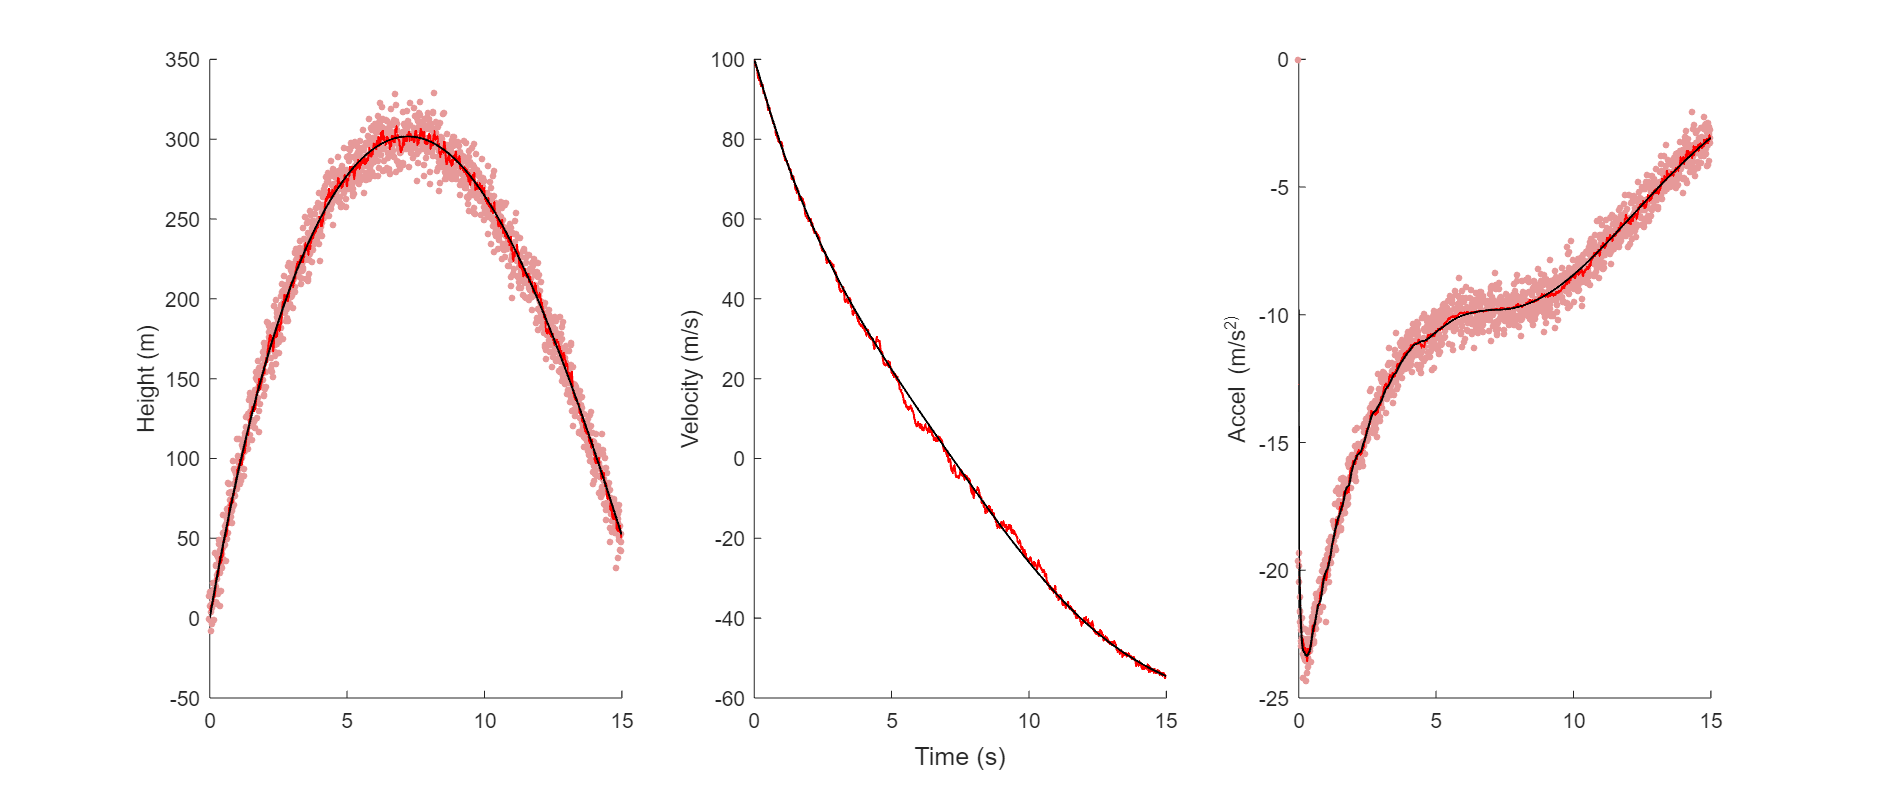

figure(1)
clf
tp = tiledlayout(1, 3);
xlabel(tp, "Time (s)")
set(gcf, 'position', [0 0 1200 500])


nexttile
hold on
scatter(data.time, data.z_meas(1:end-1), 10, "filled", "MarkerFaceColor", [0.9 0.6 0.6]);
plot(data.time, data.z_kf, "LineWidth", 1, "Color", "r")
plot(data.time, data.z_true(1:end-1), "LineWidth", 1, "Color", "k")
ylabel("Height (m)")

nexttile
hold on
plot(data.time, data.v_kf, "LineWidth", 1, "Color", "r")
plot(data.time, data.v_true(1:end-1), "LineWidth", 1, "Color", "k")
ylabel("Velocity (m/s)")

nexttile
hold on
scatter(data.time, data.a_meas(1:end-1), 10, "filled", "MarkerFaceColor", [0.9 0.6 0.6]);
plot(data.time, data.a_kf, "LineWidth", 1, "Color", "r")
plot(data.time, data.a_true(1:end-1), "LineWidth", 1, "Color", "k")
ylabel("Accel (m/s^2)")

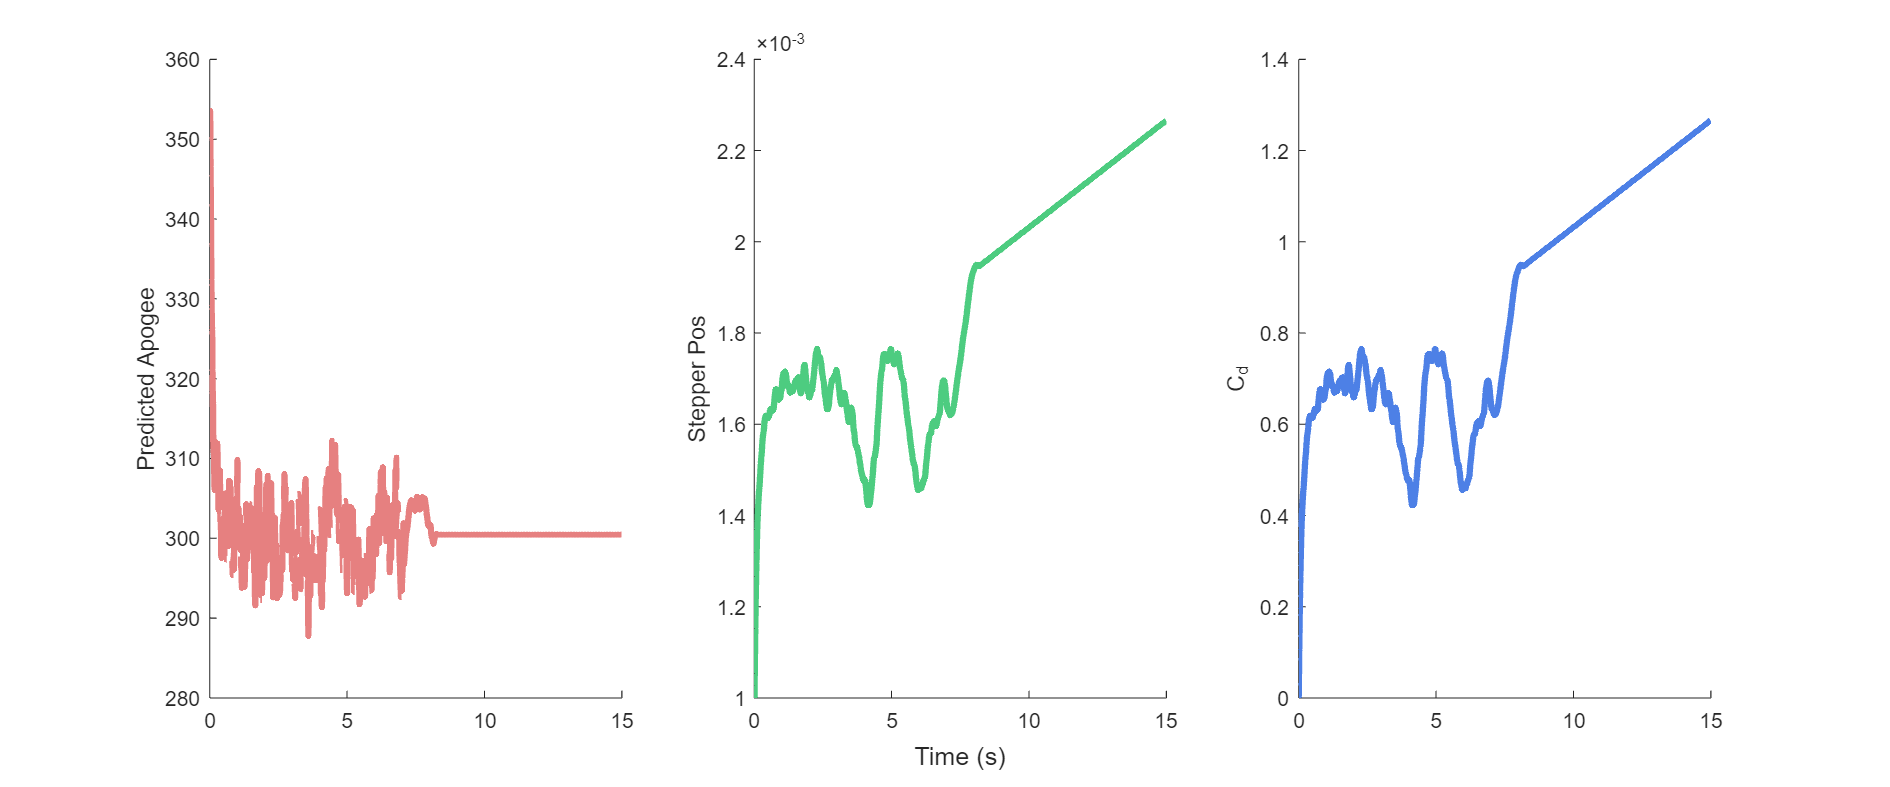


figure(2)
clf
tp = tiledlayout(1, 3);
xlabel(tp,"Time (s)")
set(gcf, 'position', [0 0 1200 500])


nexttile
hold on
plot(data.time, data.Apogee_kf, "LineWidth", 3, "Color", [0.9 0.5 0.5])
ylabel("Predicted Apogee")


nexttile
hold on
plot(data.time, data.C_d_kf, "LineWidth", 3, "Color", [0.3 0.8 0.5])
ylabel("Stepper Pos")



nexttile
hold on
plot(data.time, data.stepper_pos(1:end-1), "LineWidth", 3, "Color", [0.3 0.5 0.9])
ylabel("C_d")

function [sigma_points] = linear_trajectory_model(sigma_points, dt)  %========================STATE MODEL============================
global m

    %linear balistic eqaution with drag
    X_p = zeros(size(sigma_points(:,1))); %init empty state vector

    for i=1:length(sigma_points(1,:)) %loop through each sigma point

        X = sigma_points(:,i); %make a copy of the point for computation
        %compute new state based on old state
        X_p(1) = X(1) + X(2)*dt;
        X_p(2) = X(2) + X(3)*dt;

        X_p(5) = C_d_lookup();

        X_p(3) = -9.8 - (X(2)^2*X(5))/m*sign(X(2));
        X_p(4) = height_lookup(X);
        
   
        %write new state back to sigma point matrix
        sigma_points(:,i) = X_p;
    end
end


%========================APOGEE MODEL============================
%model of predicted apogee using ODE45 (will replace with look-up table)
function apogee = height_lookup(X)
        if X(2) < 0
            apogee = X(4);
            return
        end
        x_start = [X(1) X(2)];
        options = odeset('Events', @apogee_event); %use event func to stop solver when it reaches apogee
        [T, True_State] = ode45(@rate_func, [0, 60], x_start, options); %60s max sim time
        apogee = max(True_State(:,1));
end


%========================C_D MODEL============================
%linear model of C_d vs stepper-position
function res = C_d_lookup()
global stepper_pos
    res = stepper_pos/1000 + 0.001;
end


%========================SENSOR MODEL============================
function [sigma_points] = sensor_model(sigma_points, dt)
    sigma_points = [1 0 0 0 0 ; 0 0 1 0 0]*sigma_points;
end



%========================UNSCENTED TRANFORM ============================
function [state, cov, sigma_points] = unscented_transform(sigma_points, sigma_weights, transfer_function, dt, noise)
    global alpha
    sigma_points = transfer_function(sigma_points, dt);  %popogate points with transfer function
    state = sigma_points * sigma_weights;  %collapse new points to a single state estimate

    sigma_weights(end) = sigma_weights(end) + (1-alpha^2+2);
    cov = ((sigma_points-state)*(diag(sigma_weights)))*((sigma_points-state)') + noise;  %compute the covariance of the new state estimate

end




%========================SIGMA POINTS============================
function [sigma_points, sigma_weights] = make_sigma_points(state, cov, lambda)
global N
    
    S = sqrt((N+lambda)*cov); %can only take square root if Cov = S dot S', then sqrt(cov) = S
    
    sigma_points = state*ones(1, 2*N+1); %init the Sigma Point matrix (2N+1 by N)
    sigma_weights = zeros(2*N+1, 1);  %init the Sigma Weight matrix (N by 1)

    for i=1:N
        sigma_points(i,i) = state(i) + S(i, i); %front points
        sigma_weights(i,:) = 1/(2*(N+lambda));
    end

    for i=N+1:2*N
        sigma_points(i-N,i) = state(i-N) - S(i-N, i-N); %back points
        sigma_weights(i,:) = 1/(2*(N+lambda));
    end

    sigma_points(:,2*N+1) = state; %center point
    sigma_weights(2*N+1,:) = lambda/(N+lambda); %center point
end




%========================KALMAN UPDATE============================
function [state, state_cov] = kalman_update(state, state_cov, measurement, dt, debug)
global process_noise measurement_noise N alpha
alpha = 0.5;
% lambda = alpha^2*(N)-N;
lambda = 3;



%make sigma points and predict new state and covariance
[sigma_points, sigma_weights] = make_sigma_points(state, state_cov, lambda);
[P_state, P_state_cov, P_sigma_points] = unscented_transform(sigma_points, sigma_weights, @linear_trajectory_model, dt, process_noise);

if debug()
    sigma_points
    P_sigma_points
    P_state
    P_state_cov
    sigma_weights
end

%predict the measurment and measurement covariance
[P_measurement, P_measurement_cov, PP_sigma_points] = unscented_transform(P_sigma_points, sigma_weights, @sensor_model, dt, measurement_noise);
%compute cross correlation from predicted sate and predicted measurement

if debug()
    PP_sigma_points
    P_measurement
    P_measurement_cov
    
end
sigma_weights(end) = sigma_weights(end) +  (1-alpha^2+2);
cross_correlation = ((P_sigma_points-P_state)*(diag(sigma_weights)))*((PP_sigma_points-P_measurement)');
kalman_gain = cross_correlation/P_measurement_cov;

if debug()
    cross_correlation
    kalman_gain
end


%update the state and state covariance
state = P_state + kalman_gain*(measurement - P_measurement);
state_cov = P_state_cov - (kalman_gain*P_measurement_cov*kalman_gain');

if debug()
    state
    state_cov
end

end



%========================ODE EVENT============================



function [position,isterminal,direction] = apogee_event(~,X)
  position = X(2); % The value that we want to be zero
  isterminal = 1;  % Halt integration 
  direction = 0;   % The zero can be approached from either direction
end





%========================ODE============================

function rate = rate_func(~, X)

global m C_d
z = X(1,:);
v = X(2,:);

%calculate forces
f_drag = C_d .* v.^2 .* sign(v) .* -1;
f_grav = -9.8*m;

%calculate derivatives
dzdt = v;
dvdt = 1./m .* (f_grav + f_drag);

%construct rate vector
rate = [dzdt ; dvdt];

end




